# Support Vector Machine

clear;clc;

## Data Processing

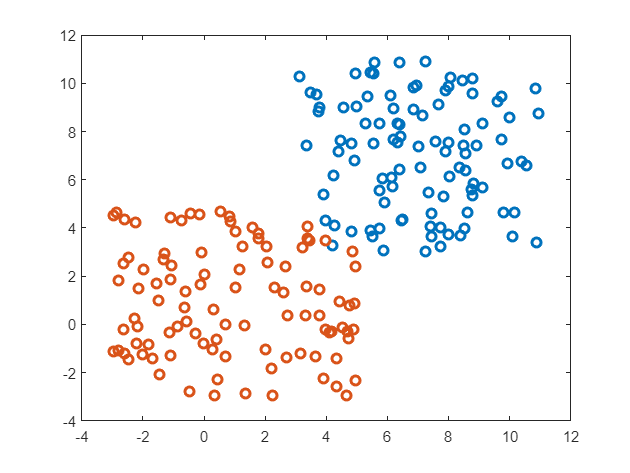

rng(123); % For reproducibility
% 
% r1 = sqrt(rand(100,1));
% t1 = 2*pi*rand(100,1);
% data1 = [r1.*cos(t1), r1.*sin(t1)];
% 
% r2 = sqrt(3*rand(100,1)+1);
% t2 = 2*pi*rand(100,1); 
% data2 = [r2.*cos(t2), r2.*sin(t2)];

sigma = 8;
data1 = rand(100,2)*sigma + 3;
data2 = rand(100,2)*sigma - 3;

plot(data1(:,1), data1(:,2), 'o', 'LineWidth',2);
hold on;
plot(data2(:,1), data2(:,2), 'o', 'LineWidth',2);

## Formulation

X = [data1; data2];
Y = [ones(size(data1,1),1); -ones(size(data2,1),1)];
H = linear_kernel(X,X);
% H = gaussian_kernel(X,X,1/sqrt(2));
% Quadprog finds minimum. So we need to specify -ve objective for maximum
H = diag(Y)*H*diag(Y);
F = -ones(size(Y,1),1);
C = 0.9;

Aeq=Y';
beq=0;
A=[]; b=[];
lb = zeros(size(Y,1),1);
ub = ones(size(Y,1),1)*C;
alpha = quadprog(H,F,A,b,Aeq,beq, lb, ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Plot Decision boundary

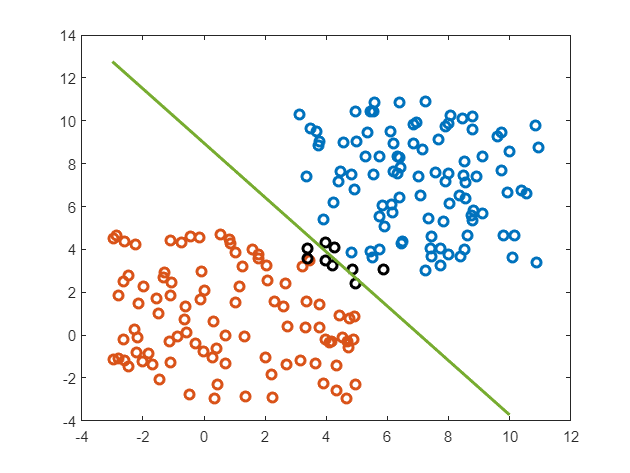

alpha = round(alpha, 6);
w = zeros(1,size(X,2));
ind = [];
for i=1:size(alpha,1)
    w = w+alpha(i)*X(i,:);
    if alpha(i)>0
        ind = [ind i];
        plot(X(i,1),X(i,2), 'o', 'Color', 'black', 'LineWidth', 2);
    end
end
b_fun = @(i) 1/Y(i) - w*X(i,:)';
b = mean(arrayfun(b_fun, ind));
y_db = @(x) -(x*w(1)+b)/w(2);
range = round(min(X(:,1)):max(X(:,1)));
plot(range, y_db(range), 'LineWidth', 2)

## Classification

Y_pred = [];
for i=1:size(X,1)
    c = 0;
    if w*X(i,:)'+b >= 0
        c = 1;
    else
        c = -1;
    end
    Y_pred = [Y_pred;c];
end

acc = sum(Y_pred==Y)/size(Y,1)

acc = 0.9900

function ker = linear_kernel(x,y)
    ker = zeros(size(x,1),size(y,1));
    for i=1:size(x,1)
        for j=1:size(y,1)
            ker(i,j) = x(i,:)*y(j,:)';
        end
    end
end

function ker = gaussian_kernel(x,y,s)
    ker = zeros(size(x,1),size(y,1));
    for i=1:size(x,1)
        for j=1:size(y,1)
            ker(i,j) = exp(-(norm(x(i,:)-y(i,:))^2)/(2*s^2));
        end
    end
end